# Ejercicio 04: Función de Decaimiento Exponencial

Muchos modelos matemáticos en ingeniería utilizan la función exponencial. La fórmula general de la función de decaimiento es:


$$y\left(t\right)=Ae^{-\tau t}$$


Donde A es el valor inicial en t=0, y tao es la constante de tiempo para la función. Escriba un script para estudiar el efecto de la constante de tiempo. Para simplificar la ecuación, establecer A igual a 1. Solicite al usuario dos valores diferentes para la constante de tiempo y para valores iniciales y finales para el rango de un vector t. Luego, calcular dos vectores diferentes de (y), usando la ecuación anterior y las dos constantes de tiempo, y graficar ambas funciones exponenciales en la misma gráfica dentro del rango que el usuario especificó. Utilice una función para realizar el cálculo. Asegúrese de etiquetar la gráfica y ambos ejes. ¿Qué sucede con la tasa de decaimiento a medida que la constante de tiempo se vuelve más grande?

%Valores para la cste de tiempo
tao1 = input("Digite el valor de la cte de tiempo 1: ")

tao1 = 0.0100

tao2 = input("Digite el valor de la cte de tiempo 2: ")

tao2 = 0.0600


%Valores iniciales y finales del tiempo
t_inicial = input("Digite el tiempo inicial: ")

t_inicial = 0

t_final = input("Digite el tiempo final: ")

t_final = 100


%Crear el vector del tiempo
vectorT = linspace(t_inicial,t_final,50)

vectorT =          0    2.0408    4.0816    6.1224    8.1633   10.2041   12.2449   14.2857   16.3265   18.3673   20.4082   22.4490   24.4898   26.5306   28.5714   30.6122   32.6531   34.6939   36.7347   38.7755   40.8163   42.8571   44.8980   46.9388   48.9796   51.0204   53.0612   55.1020   57.1429   59.1837   61.2245   63.2653   65.3061   67.3469   69.3878   71.4286   73.4694   75.5102   77.5510   79.5918   81.6327   83.6735   85.7143   87.7551   89.7959   91.8367   93.8776   95.9184   97.9592  100.0000



sol1 = calcularDecaimiento(tao1,vectorT)

y =     1.0000    0.9798    0.9600    0.9406    0.9216    0.9030    0.8848    0.8669    0.8494    0.8322    0.8154    0.7989    0.7828    0.7670    0.7515    0.7363    0.7214    0.7068    0.6926    0.6786    0.6649    0.6514    0.6383    0.6254    0.6128    0.6004    0.5882    0.5764    0.5647    0.5533    0.5421    0.5312    0.5205    0.5099    0.4996    0.4895    0.4797    0.4700    0.4605    0.4512    0.4421    0.4331    0.4244    0.4158    0.4074    0.3992    0.3911    0.3832    0.3755    0.3679


sol1 =     1.0000    0.9798    0.9600    0.9406    0.9216    0.9030    0.8848    0.8669    0.8494    0.8322    0.8154    0.7989    0.7828    0.7670    0.7515    0.7363    0.7214    0.7068    0.6926    0.6786    0.6649    0.6514    0.6383    0.6254    0.6128    0.6004    0.5882    0.5764    0.5647    0.5533    0.5421    0.5312    0.5205    0.5099    0.4996    0.4895    0.4797    0.4700    0.4605    0.4512    0.4421    0.4331    0.4244    0.4158    0.4074    0.3992    0.3911    0.3832    0.3755    0.3679


sol2 = calcularDecaimiento(tao2,vectorT)

y =     1.0000    0.8848    0.7828    0.6926    0.6128    0.5421    0.4797    0.4244    0.3755    0.3322    0.2939    0.2600    0.2301    0.2036    0.1801    0.1593    0.1410    0.1247    0.1104    0.0976    0.0864    0.0764    0.0676    0.0598    0.0529    0.0468    0.0414    0.0367    0.0324    0.0287    0.0254    0.0225    0.0199    0.0176    0.0156    0.0138    0.0122    0.0108    0.0095    0.0084    0.0075    0.0066    0.0058    0.0052    0.0046    0.0040    0.0036    0.0032    0.0028    0.0025


sol2 =     1.0000    0.8848    0.7828    0.6926    0.6128    0.5421    0.4797    0.4244    0.3755    0.3322    0.2939    0.2600    0.2301    0.2036    0.1801    0.1593    0.1410    0.1247    0.1104    0.0976    0.0864    0.0764    0.0676    0.0598    0.0529    0.0468    0.0414    0.0367    0.0324    0.0287    0.0254    0.0225    0.0199    0.0176    0.0156    0.0138    0.0122    0.0108    0.0095    0.0084    0.0075    0.0066    0.0058    0.0052    0.0046    0.0040    0.0036    0.0032    0.0028    0.0025


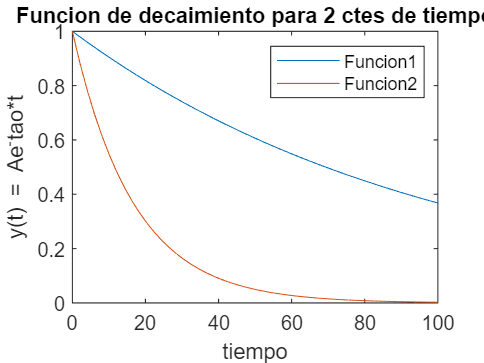


%Graficar la solucion
figure
plot(vectorT,sol1)
hold on
plot(vectorT,sol2)
legend("Funcion1","Funcion2")
title("Funcion de decaimiento para 2 ctes de tiempo")
xlabel("tiempo")
ylabel("y(t) = Ae^-tao*t")

Crear la funcion para calcular decaimiento

function y = calcularDecaimiento(tao,tiempo)
y = exp(-tao .* tiempo)
end